Mikołaj Suchoń

Task 1

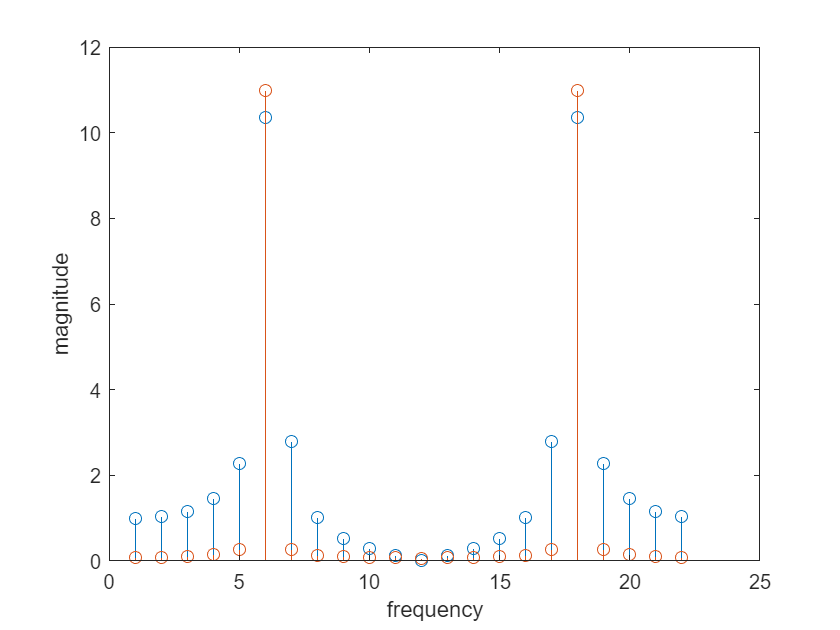

clear
n=0:21;
w1=(10*pi)/21;
w2=(9.5*pi)/21;
x1=cos(w1*n);
x2=cos(w2*n);
X1=fft(x1);
X2=fft(x2);
m1=abs(X1);
m2=abs(X2);
stem(m1);hold on;
stem(m2);
hold off;
xlabel('frequency');
ylabel('magnitude');

Task 2

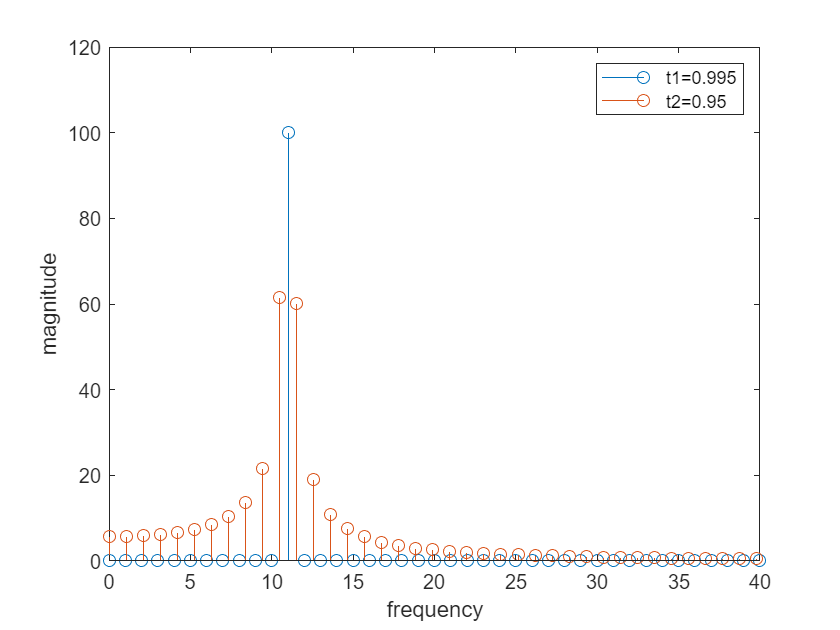

clear;
fs=200;
T=1/fs;
freq=11;
t1=0:T:0.995;
n1=length(t1);
df1=fs/n1;
t2=0:T:0.95;
n2=length(t2);
df2=fs/n2;
x1=sin(2*pi*freq*t1);
x2=sin(2*pi*freq*t2);
X1=fft(x1);
X2=fft(x2);
m1=abs(X1);
m2=abs(X2);
f1=df1*(0:n1-1);
stem(f1,m1);
hold on
f2=df2*(0:n2-1);
stem(f2,m2);
xlim([0 40]);
xlabel('frequency');
ylabel('magnitude');
legend('t1=0.995','t2=0.95');
hold off;

Task 3

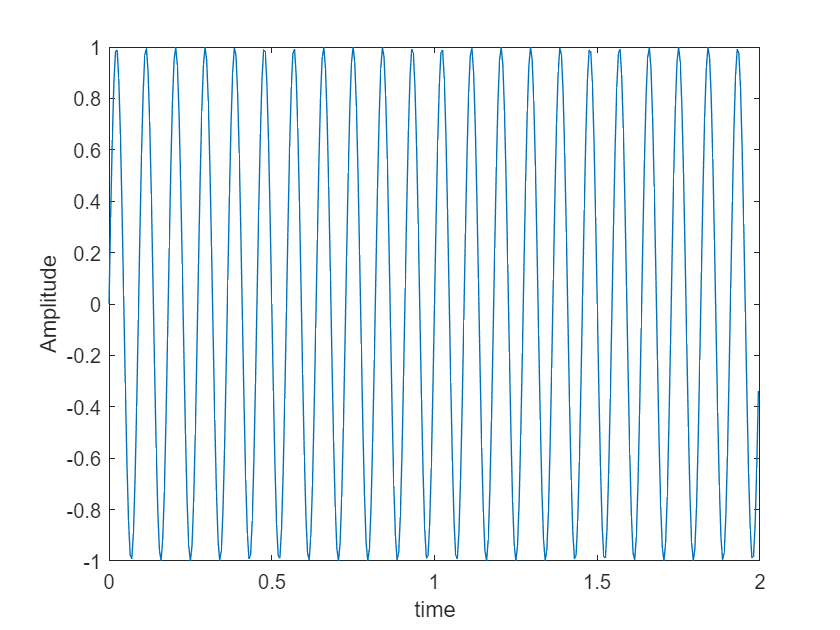

t3=0:T:0.995*2+T;
x=[x1,x1];
plot(t3,x);
xlabel('time');
ylabel('Amplitude');

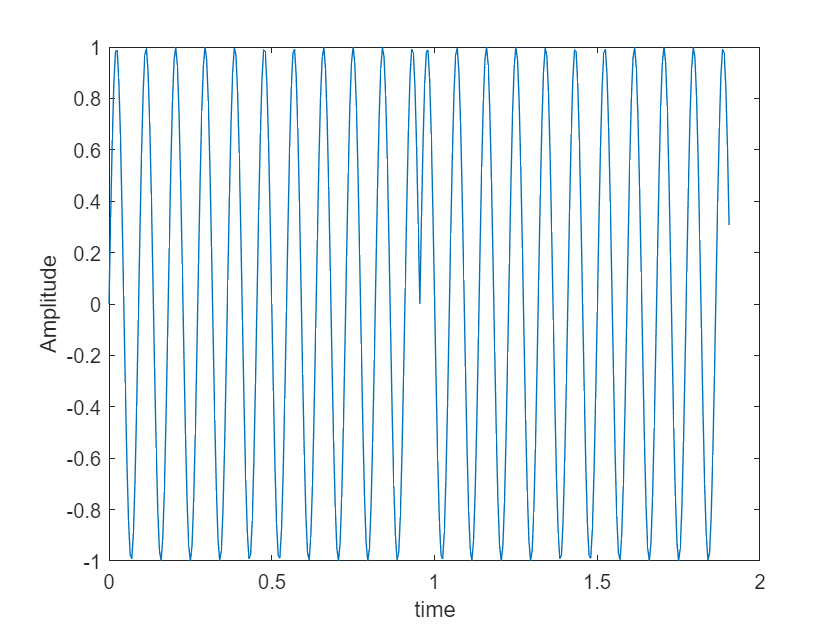

t4=0:T:0.95*2+T;
x3=[x2,x2];
plot(t4,x3);
xlabel('time');
ylabel('Amplitude');

Task 4

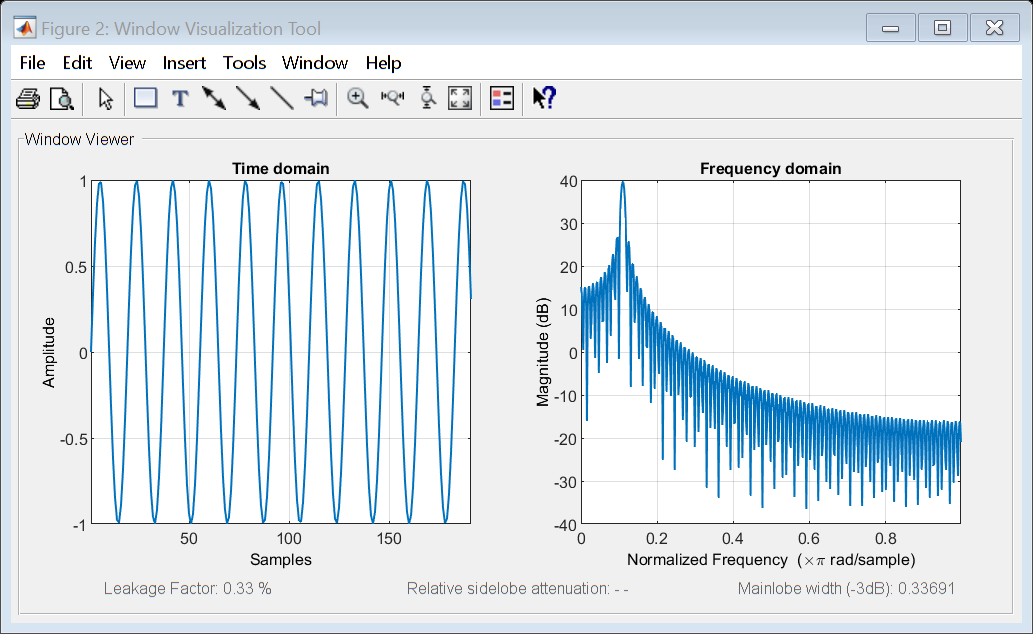

clear;
fs=200;
T=1/fs;
freq=11;
t=0:T:0.95;
n=length(t);
df=fs/n;
x=sin(2*pi*freq*t);
w=rectwin(191);
wx=x.*w';
wvtool(x)

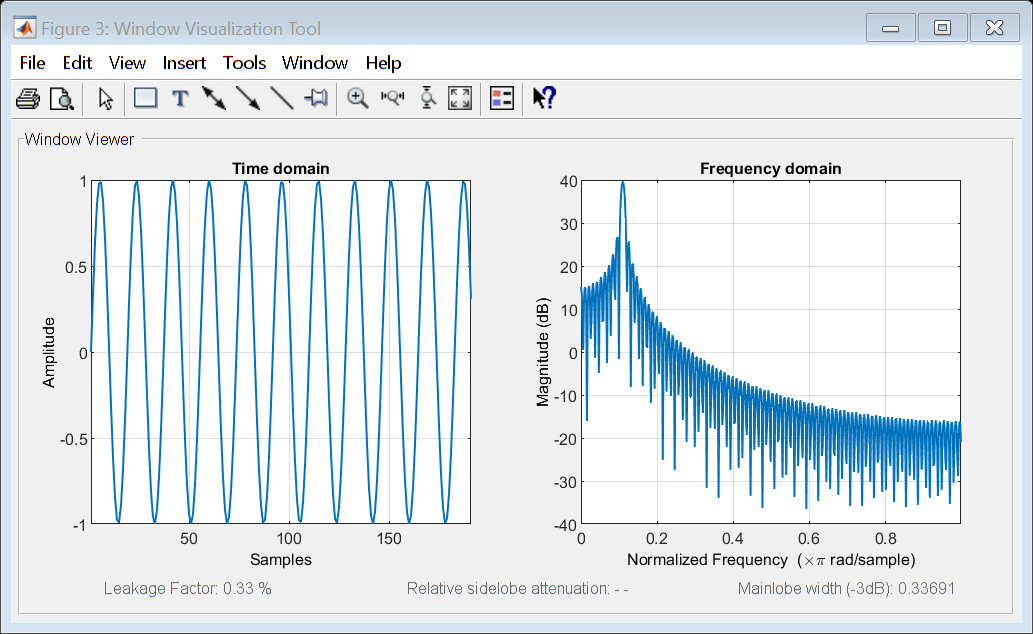

wvtool(wx)

Above we observe time and frequency plots for signal modulated by a rectangular window

No changes to primary signal made; rectangular window doesnt influence the signal

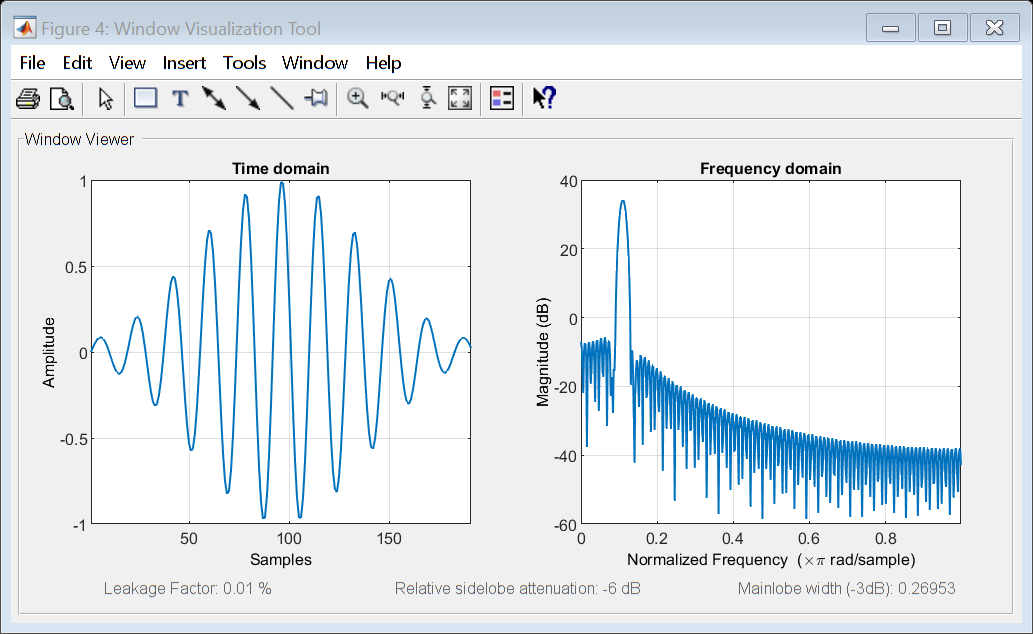

w2=hamming(191);
wx2=x.*w2';
wvtool(wx2)

Above we observe time and frequency plots for signal modulated by a Hamming window

We observe a magnitude decreace by 7 dB on the spectrogram but the peak is much more pronounced (clearer)

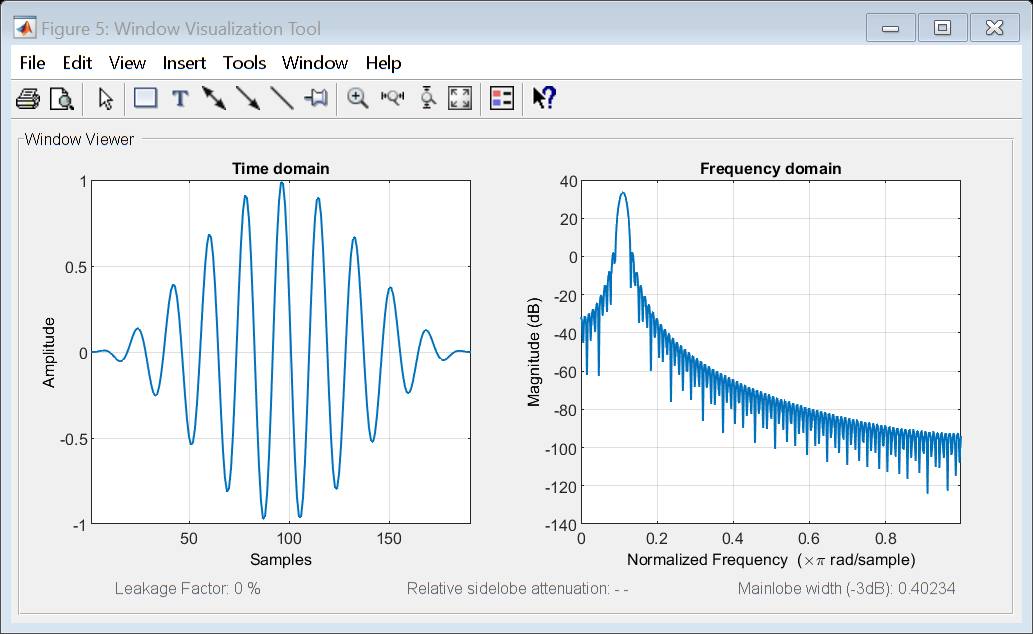

w3=hann(191);
wx3=x.*w3';
wvtool(wx3);

Above we observe time and frequency plots for signal modulated by a Hann window

We again observe a magnitude decreace by 7 dB on the spectrogram but the peak now is as pronounced as in primary signal in respect to the magnitude and is stretched in respect to frequency

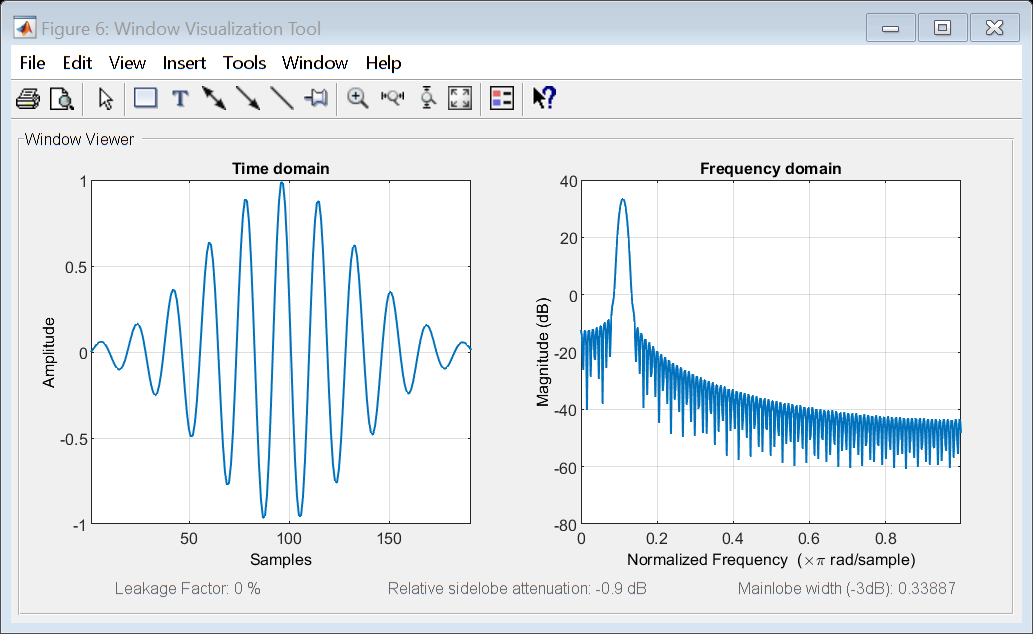

wx4=x.*gausswin(191)';
wvtool(wx4)

Above we observe time and frequency plots for signal modulated by a Gaussian window

Here we observe a similar magnitude decreace to previous windows with a peak clear, similar to Hamming window

Task 5

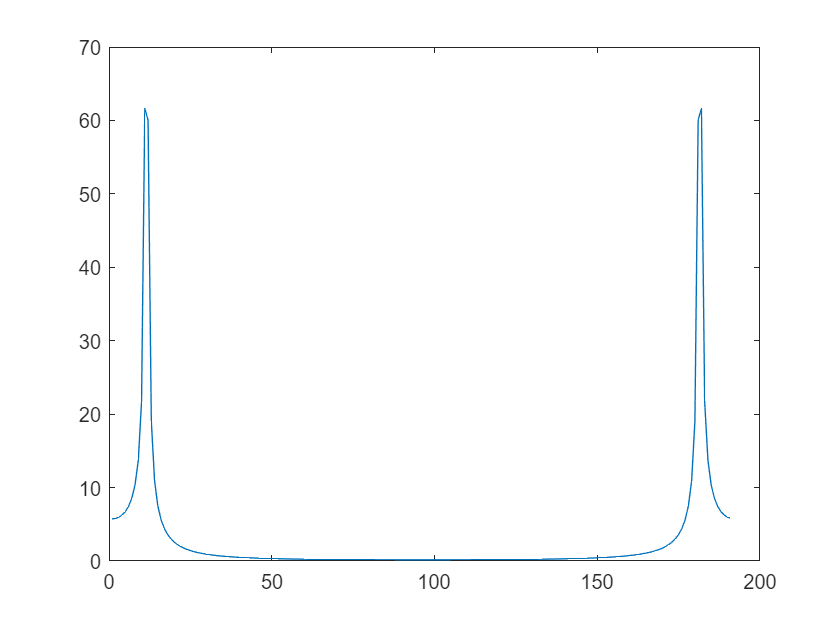

X0=fft(x,256);
X=fft(wx,256);
X2=fft(wx2,256);
X3=fft(wx3,256);
X4=fft(wx4,256);
f=df*(0:256-1);
plot(abs(fft(x)))

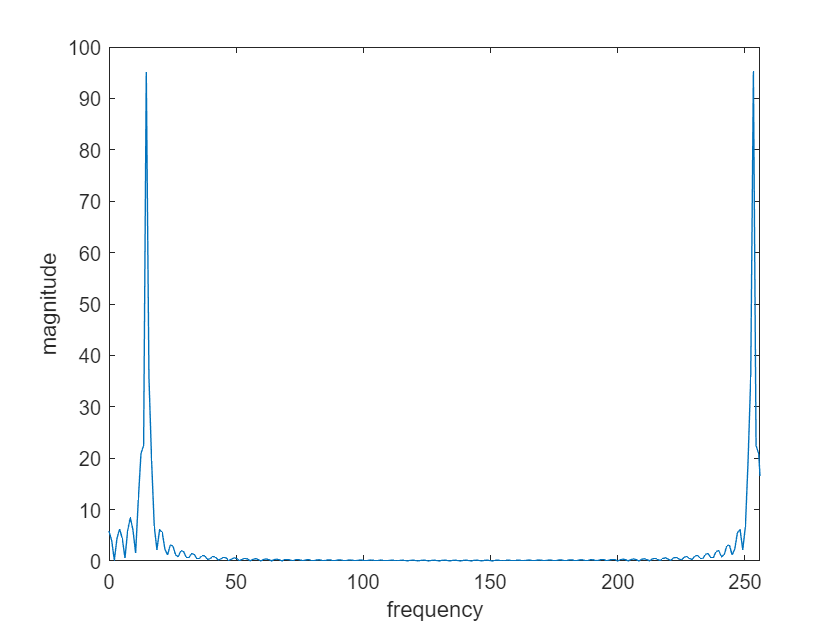

plot(f,abs(X0))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

plot(abs(fft(wx)))

plot(f,abs(X))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

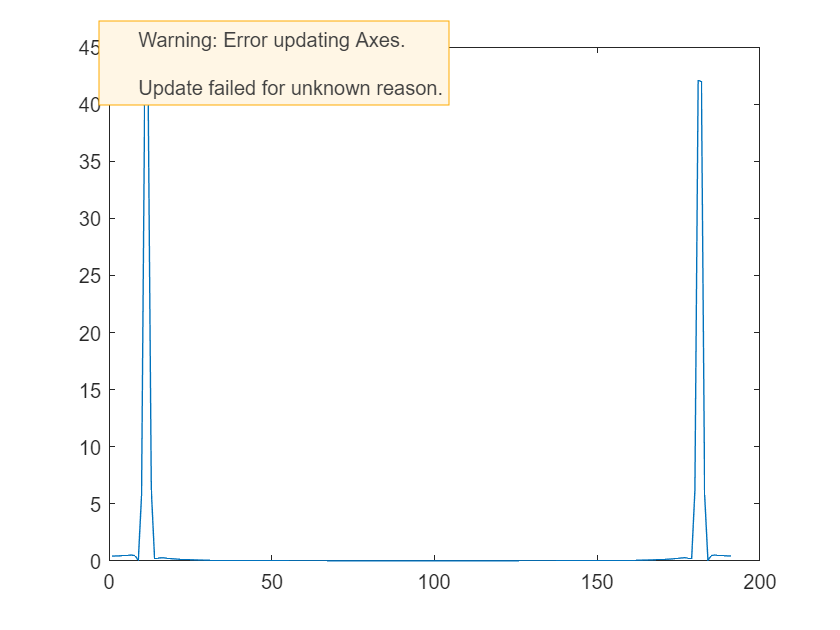

plot(abs(fft(wx2)))

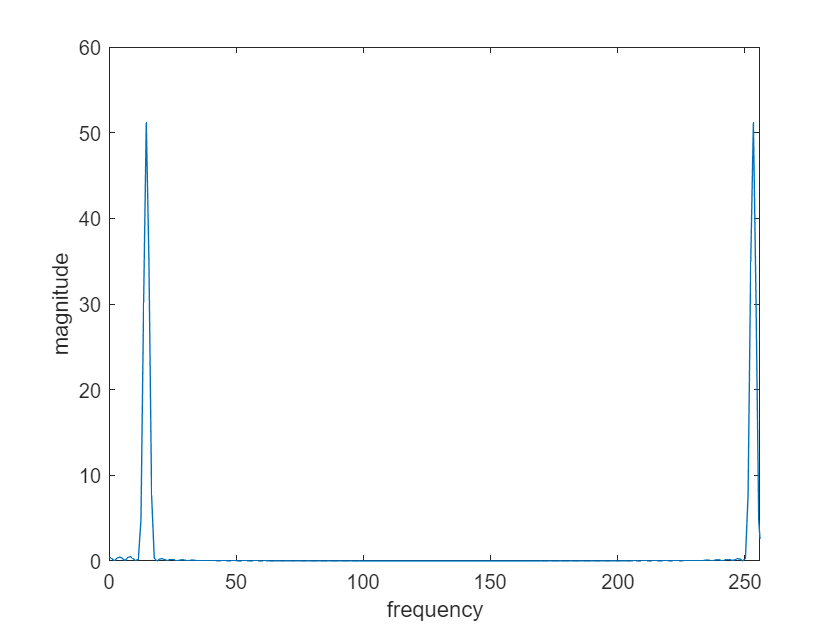

plot(f,abs(X2))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

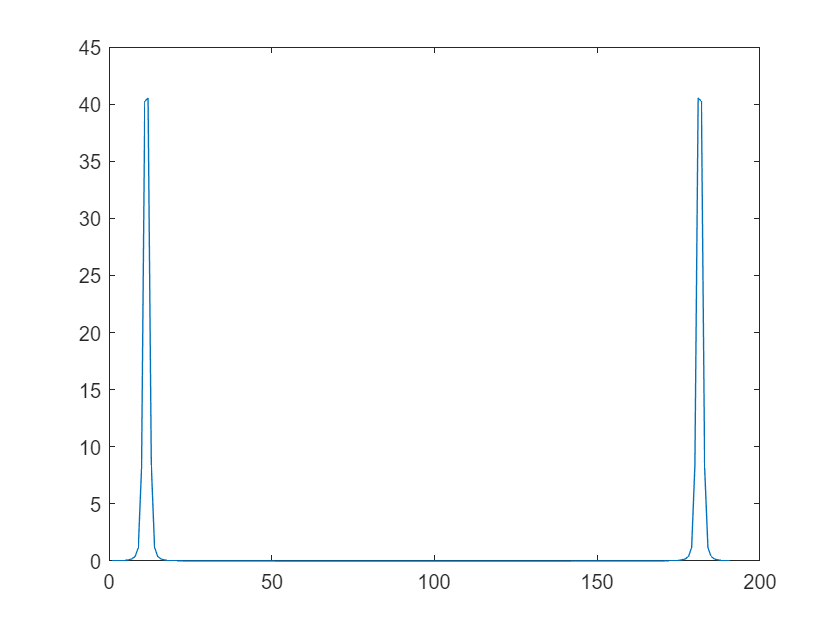

plot(abs(fft(wx3)))

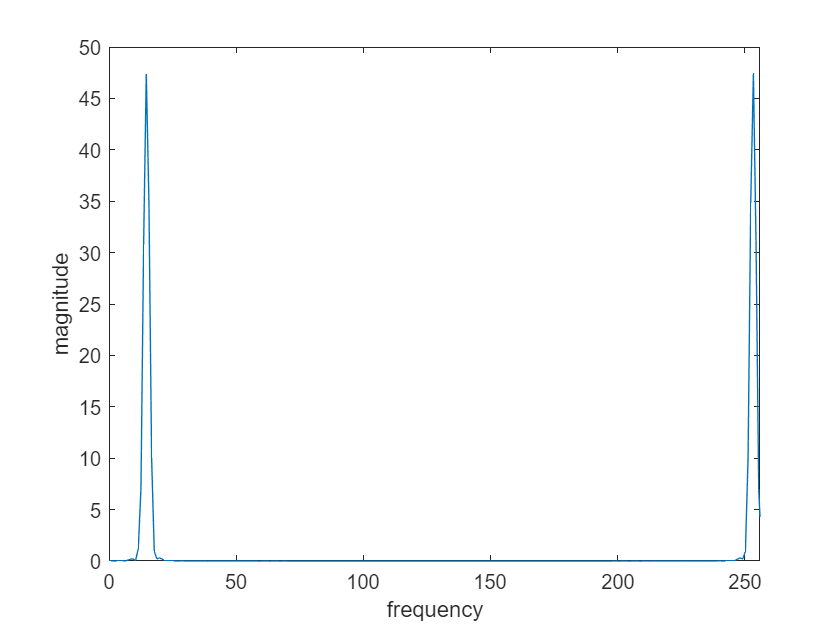

plot(f,abs(X3))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

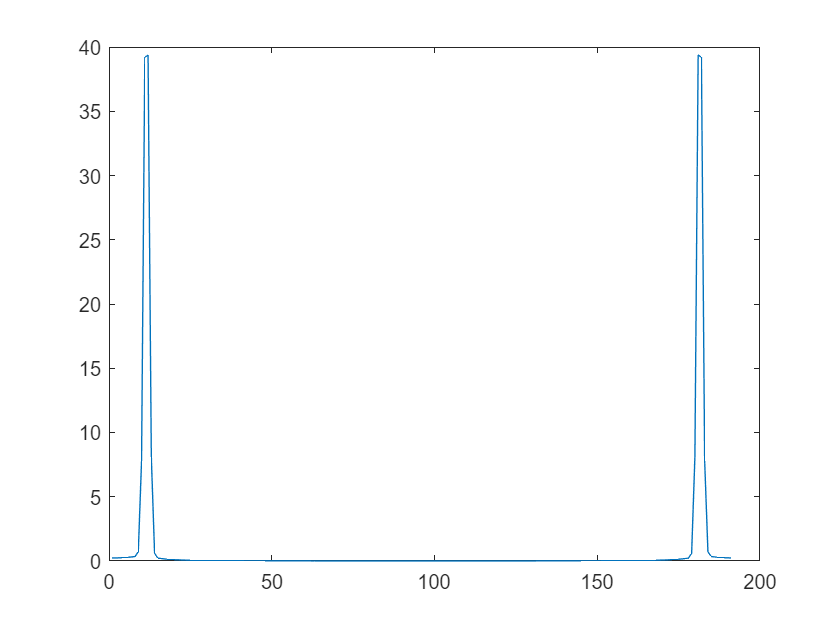

plot(abs(fft(wx4)))

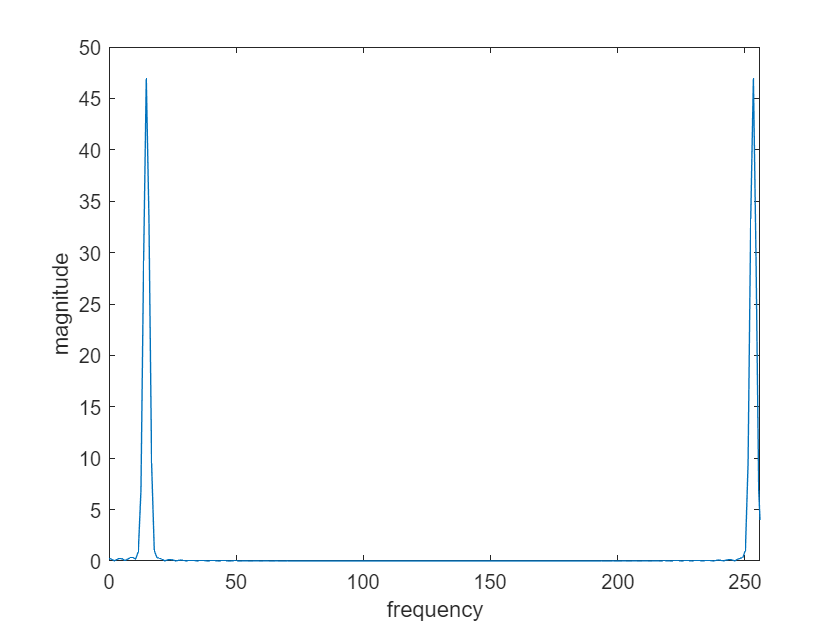

plot(f,abs(X4))
xlim([0 256]);
xlabel('frequency');
ylabel('magnitude');

## Task 6)

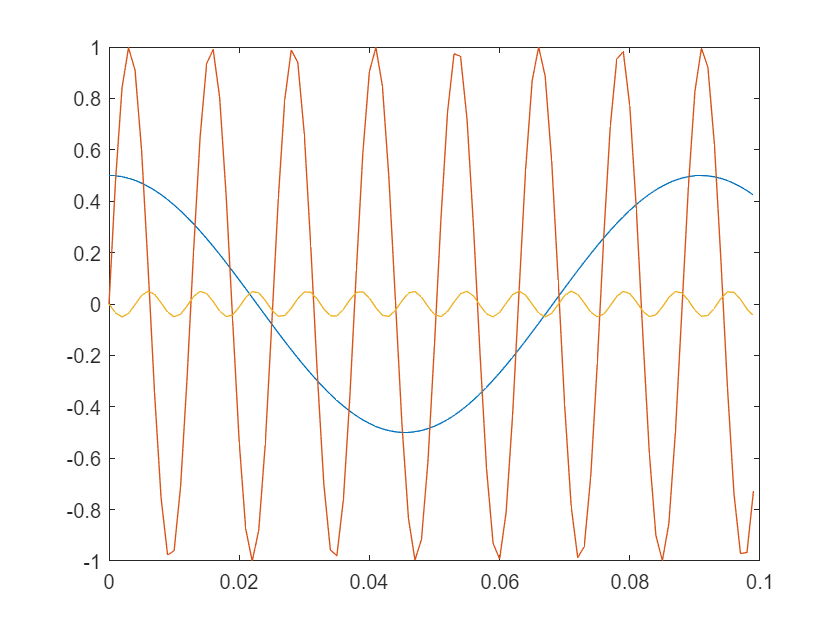

fs = 1e3;

dt=1/fs;

t = 0:dt:(.1-1/fs);
N=length(t);
df=fs/N-1;

f = [11 79.5 123.1];
phi = [90 0 180].* pi/180;
A = [.5 1 .05];
clear s
for n=1:3
s(n,:) = A(n)*sin(2*pi*f(n)*t+phi(n));
end
s_sum = sum(s);

plot(t,s);

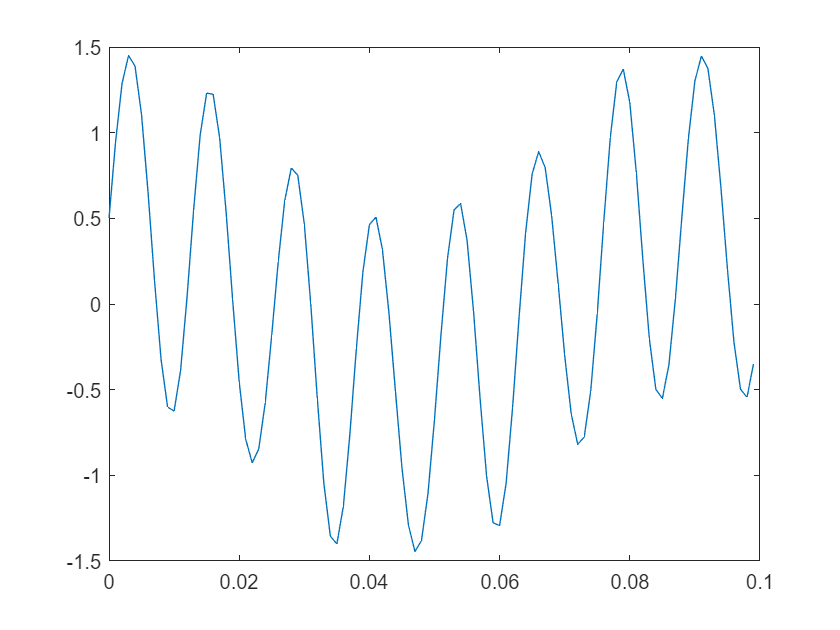

plot(t,s_sum);

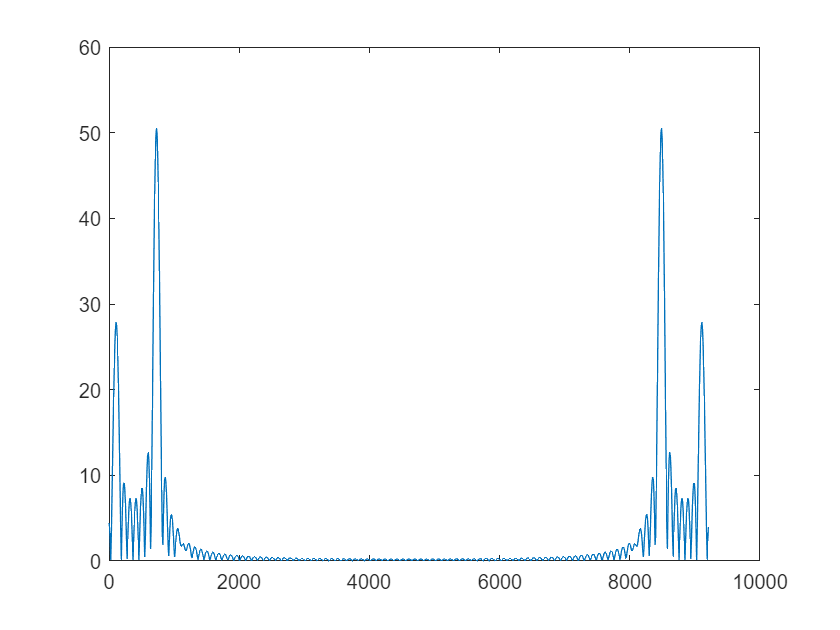

S=fft(s_sum,1024);
mag=abs(S);
ph=rad2deg(unwrap(angle(S)));
F=df*(0:1023);
plot(F,mag);

because of leakage we cannot see 3 peaks coresponding to 3 sin waves

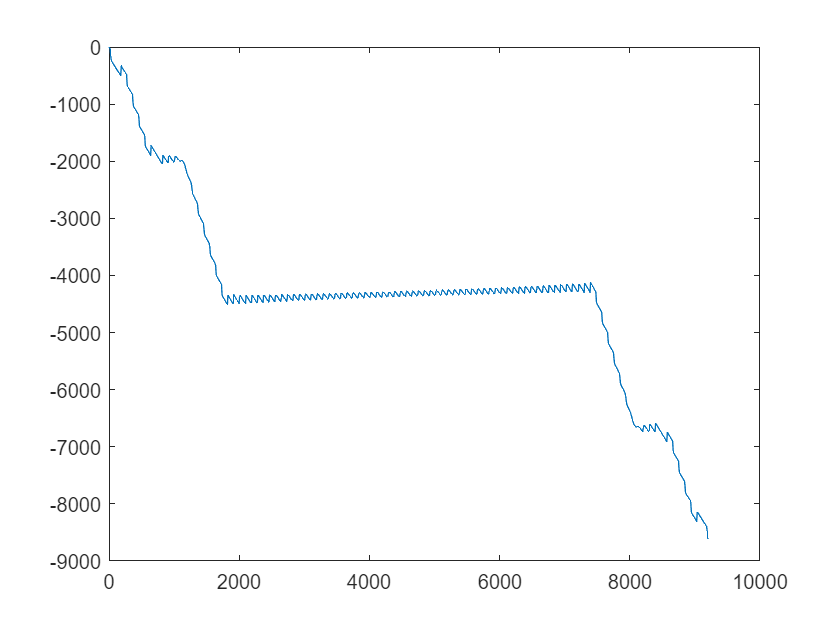


%xlim([0 1024])%add freq
plot(F,ph);

we fail to oserve the phase of above mentioned waves

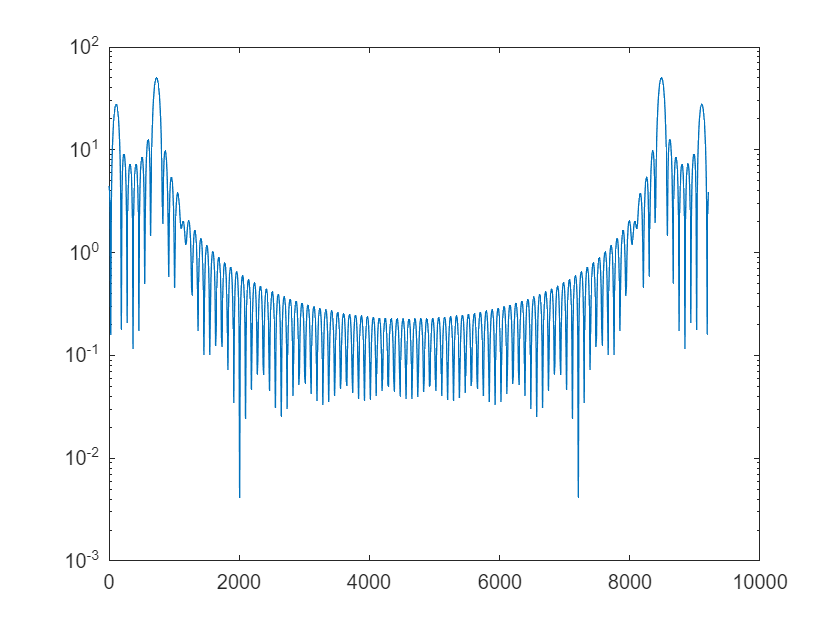

%xlim([0 1024])
semilogy(F,mag)

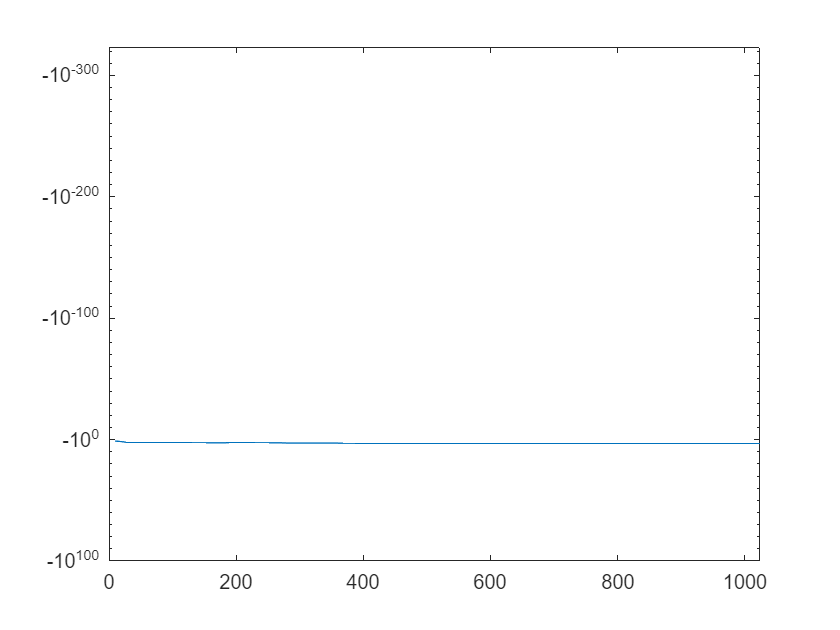

%xlim([0 1024])
semilogy(F,(ph))
xlim([0 1024])

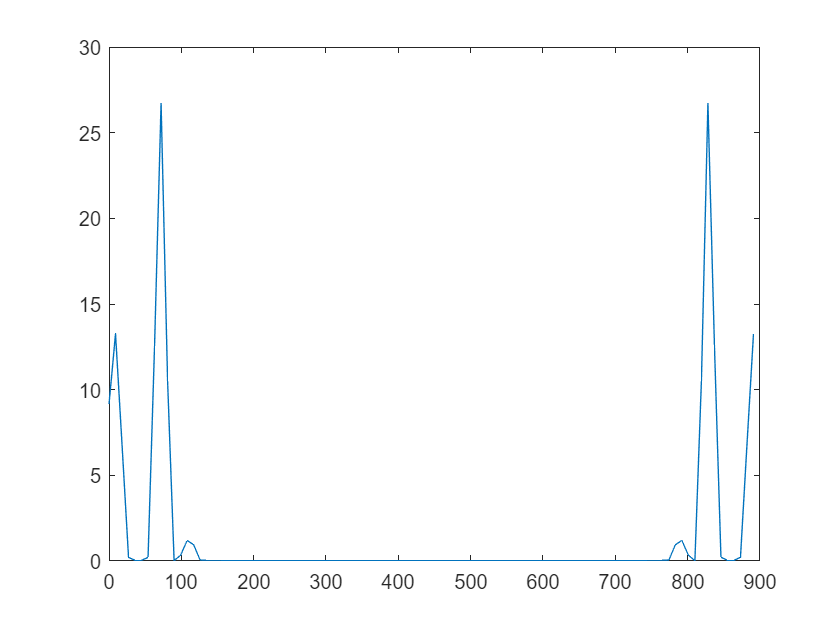

wv=s_sum.*hamming(100)';
W=fft(wv);
magw=abs(W);
pw=rad2deg(unwrap(angle(W)));
F=df*(0:N-1);
plot(F,magw)

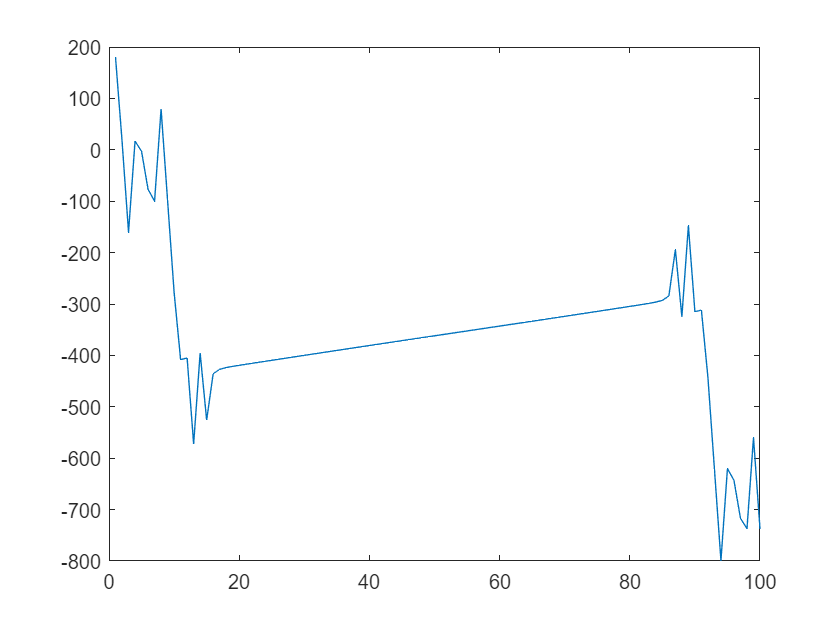

plot(pw)

Comparing results from zero-padded specrum to original we conclude that a excessive zero padding introduces noise into our analysis 